# Proyecto Integrador IV - Planificación y control

Integrantes:  - William Andrade Gonzalez

                     - Glen Alejandro Guerrero Burbano

## GENERAR EL MAPA Y ENGROSAR OBSTACULOS

Se crea el mapa con los obstaculos

clear; clc; close all;

disp("Punto INICIAL de la trayectoria en un mapa de 20x20 metros^2")

Punto INICIAL de la trayectoria en un mapa de 20x20 metros^2


p_inicial = input("Ingrese la posición INICIAL del robot como vector en metros [X, Y]: ");

disp("Punto FINAL de la trayectoria")

Punto FINAL de la trayectoria


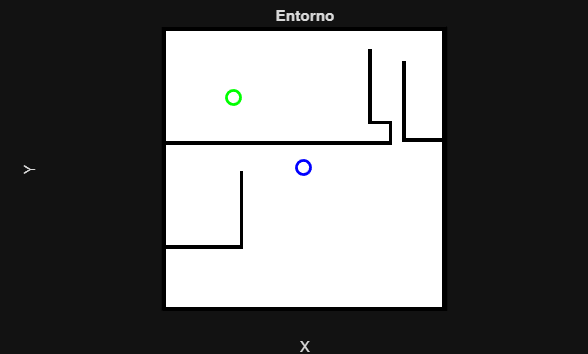

p_final = input("Ingrese la posición FINAL del robot como vector en metros [X, Y]: ");

%Se multiplican por 10 para pasar de metros a pixeles de la imagen inicial
q_start = [(p_inicial(1)*10), (p_inicial(2)*10)];
q_goal  = [(p_final(1)*10), (p_final(2)*10)]; 

% q_start = [60, 10];
% q_goal  = [50, 80]; 

% 1. Generar el mapa inicial
addpath("auxiliar");
map = dibujarMapaV2(q_start, q_goal,'mapa_optimizado.png');

[rows, cols] = size(map)

rows = 201

cols = 201

## PLANIFICACION BASADA EN REJILLA (GRID)

Se construira una rejilla uniforme a partir del mapa y se implementaran los algoritmos de busqueda BFS, DFS, A*. Dibujar cada estrategia de busqueda en una figura independendiente.

Al emplear un tamaño de celda 2, vamos a asumir que no es necesario un mayor engrosamiento de los obstaculos (los caminos pueden rozar las paredes)

% 1) Convertir el mapa a una rejilla más gruesa (tamaño celda = 2).
cell_size = 4;
grid_rows = ceil(rows / cell_size);
grid_cols = ceil(cols / cell_size);

% 2) grid_map = zeros(grid_rows, grid_cols);
for i = 1:grid_rows
    for j = 1:grid_cols
        r_start = (i-1) * cell_size + 1;  r_end = min(i * cell_size, rows); 
        c_start = (j-1) * cell_size + 1;  c_end = min(j * cell_size, cols);
        block = map(r_start:r_end, c_start:c_end);
        if any(block(:) == 1), grid_map(i, j) = 1; end
    end
end

% Convertir inicio y meta a coordenadas de celda
start_node = [ceil(q_start(2)/cell_size), ceil(q_start(1)/cell_size)];
goal_node  = [ceil(q_goal(2)/cell_size), ceil(q_goal(1)/cell_size)];
start_node = max([1 1], min(start_node, [grid_rows, grid_cols]));
goal_node  = max([1 1], min(goal_node,  [grid_rows, grid_cols]));

fprintf('Calculando ruta inicial...\n');

Calculando ruta inicial...


ruta_inicial = a_star_grid(grid_map, start_node, goal_node);

if isempty(ruta_inicial)
    disp('No se encontró una ruta inicial.');
    return;
end

% --- NUEVO: SISTEMA DE HISTORIAL DE RUTAS ---
historial_rutas = {ruta_inicial}; % Guardamos la primera ruta
colores_rutas = lines(10); % Generamos una paleta de colores para las rutas
% 4) GRAFICAR EL ENTORNO DE SIMULACIÓN
figure('Name', 'Simulación A* - Múltiples Replanificaciones', 'Position', [100, 100, 800, 600]); 
axis ij; axis equal; hold on;
axis([0.5 grid_cols+0.5 0.5 grid_rows+0.5]); set(gca, 'Color', 'w');

% Fondo y rejilla
rectangle('Position', [0.5, 0.5, grid_cols, grid_rows], 'FaceColor', 'w', 'EdgeColor', 'k');
for r = 0.5:1:grid_rows+0.5, plot([0.5, grid_cols+0.5], [r, r], 'Color', [0.9 0.9 0.9]); end
for c = 0.5:1:grid_cols+0.5, plot([c, c], [0.5, grid_rows+0.5], 'Color', [0.9 0.9 0.9]); end

% Dibujar obstáculos iniciales
[obs_rows, obs_cols] = find(grid_map == 1);
for k = 1:length(obs_rows)
    fill([obs_cols(k)-0.5, obs_cols(k)+0.5, obs_cols(k)+0.5, obs_cols(k)-0.5], ...
         [obs_rows(k)-0.5, obs_rows(k)-0.5, obs_rows(k)+0.5, obs_rows(k)+0.5], ...
         'k', 'EdgeColor', 'none'); 
end

% Dibujar Inicio y Meta
plot(start_node(2), start_node(1), 'go', 'MarkerSize', 12, 'LineWidth', 3);
plot(goal_node(2), goal_node(1), 'bx', 'MarkerSize', 12, 'LineWidth', 3);

% --- TEXTO Y DIBUJO DE LA RUTA 1 ---
h_rutas = gobjects(1, 10); 
h_rutas(1) = plot(ruta_inicial(:,2), ruta_inicial(:,1), '.-', 'Color', colores_rutas(1,:), 'LineWidth', 2, 'MarkerSize', 12);
text(start_node(2)+0.5, start_node(1)-1, 'Ruta 1', 'Color', colores_rutas(1,:), 'FontWeight', 'bold', 'FontSize', 10, 'BackgroundColor', 'w', 'Margin', 1);

h_robot = plot(ruta_inicial(1,2), ruta_inicial(1,1), 'mo', 'MarkerFaceColor', 'm', 'MarkerSize', 10);
title('Trayectoria 1 (Ruta Inicial)');
drawnow;


## Parametros simulación obstaculos y trayectorias emergentes

ruta_actual = ruta_inicial;
pos_idx = 10; %#Rejilla aproximada de donde saldrá el otro obstaculo
obstaculos_generados = 0;
max_obstaculos_dinamicos = 1; % Máximo de obstáculos que aparecerán 1

## Simulación movimiento robot y obstáculos aleatorios

Se ha generado una simulación donde se simula el movimiento del robot con la matriz PATH que representa las coordenadas x,y de los nodos que sigue la trayectoria del robot (Es una movimiento ideal); En la práctica este movimiento deberá ser implementado con los algoritmos de lectura de sensores o odometría e incluso al control del robot. Por ahora se lo hace de una manera ideal desde simulación para enfocarse más en la planificación.

while pos_idx < size(ruta_actual, 1)
    pos_idx = pos_idx + 1;
    nodo_actual = ruta_actual(pos_idx, :);
    
    set(h_robot, 'XData', nodo_actual(2), 'YData', nodo_actual(1));
    drawnow;
    pause(0.1); 
    
    % --- EVENTO ALEATORIO: Probabilidad del 8% por paso de generar obstáculo ---
    % Solo si no hemos llegado al máximo y si estamos lo suficientemente lejos de la meta
    pasos_restantes = size(ruta_actual, 1) - pos_idx;
    if rand() < 0.08 && obstaculos_generados < max_obstaculos_dinamicos && pasos_restantes > 5
        
        obstaculos_generados = obstaculos_generados + 1;
        
        % Colocar obstáculo unos pasos adelante de la posición actual del robot
        distancia_adelante = randi([2, 5]); 
        obs_dyn = ruta_actual(pos_idx + distancia_adelante, :);
        
        % Para asegurar el bloqueo, hacemos un obstáculo de 2x2 celdas
        r_min = max(1, obs_dyn(1)-1); r_max = min(grid_rows, obs_dyn(1)+1);
        c_min = max(1, obs_dyn(2)-1); c_max = min(grid_cols, obs_dyn(2)+1);
        
        % Prevenir que el obstáculo se genere exactamente sobre la meta
        if ~(r_min <= goal_node(1) && goal_node(1) <= r_max && c_min <= goal_node(2) && goal_node(2) <= c_max)
            grid_map(r_min:r_max, c_min:c_max) = 1;
            
            % Dibujarlo en rojo
            for r_obs = r_min:r_max
                for c_obs = c_min:c_max
                    fill([c_obs-0.5, c_obs+0.5, c_obs+0.5, c_obs-0.5], ...
                         [r_obs-0.5, r_obs-0.5, r_obs+0.5, r_obs+0.5], ...
                         'r', 'EdgeColor', 'k');
                end
            end
            title(sprintf('¡Obstáculo # %d detectado!', obstaculos_generados), 'Color', 'r');
            drawnow; pause(0.4);
        end
    end
    
    % --- DETECCIÓN: Verificar si la ruta restante es válida ---
    ruta_invalida = false;
    for k = pos_idx:size(ruta_actual, 1)
        if grid_map(ruta_actual(k, 1), ruta_actual(k, 2)) == 1
            ruta_invalida = true;
            break;
        end
    end
    

#### Replanificación ruta

La mejor forma para integrar el control cuando aparece un obstaculo aleatorio. Cada vez que ocurra un **evento de replanificación se agregan waypoints de la función**

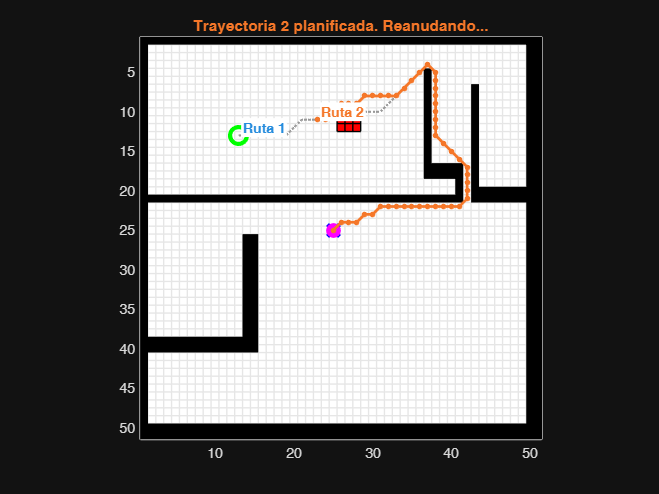

Ruta 1 bloqueada. Planificando nueva trayectoria


    % --- REPLANIFICACIÓN ---
    if ruta_invalida
        num_ruta = length(historial_rutas) + 1;
        disp(['Ruta ' num2str(num_ruta-1) ' bloqueada. Planificando nueva trayectoria']);
        
        % Cambiar el estilo de la ruta vieja a gris punteado
        set(h_rutas(num_ruta-1), 'LineStyle', ':', 'Color', [0.6 0.6 0.6], 'Marker', 'none', 'LineWidth', 1.5);
        
        % Calcular nueva ruta desde nodo actual
        nueva_ruta = a_star_grid(grid_map, nodo_actual, goal_node);
        


        % 1. Actualizas tus waypoints con la nueva ruta
        nuevos_waypoints = generarWaypoints(ruta_actual, cell_size, 10);
        
        % 2. Le pasas la nueva ruta al controlador que ya está corriendo
        controladorPP.Waypoints = nuevos_waypoints;
        

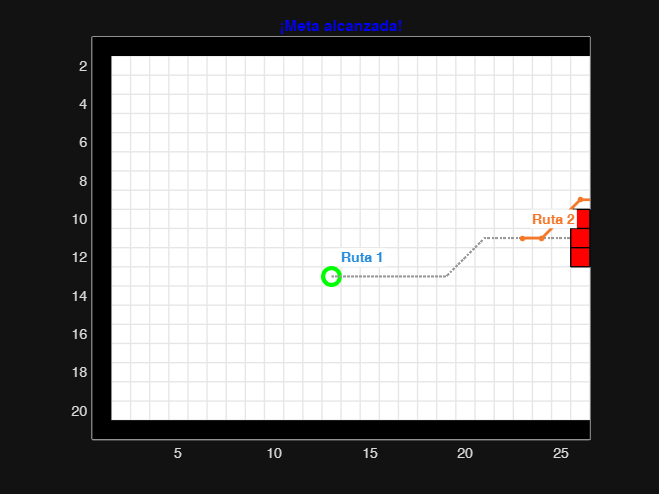

        
        if isempty(nueva_ruta)
            title('ERROR: El robot está completamente atrapado.', 'Color', 'r');
            break;
        else
            ruta_actual = nueva_ruta;
            historial_rutas{end+1} = ruta_actual; % Añadir al historial
            pos_idx = 1; 
            
            % 2. Dibujar la nueva ruta con un nuevo color
            color_nuevo = colores_rutas(mod(num_ruta-1, size(colores_rutas,1))+1, :);
            h_rutas(num_ruta) = plot(ruta_actual(:,2), ruta_actual(:,1), '.-', 'Color', color_nuevo, 'LineWidth', 2, 'MarkerSize', 12);
            
            % 3. --- NUEVO: TEXTO EN EL INICIO DE LA NUEVA RUTA ---
            % Desplazamos ligeramente el texto (+0.5, -1) para que no tape la línea
            texto_ruta = sprintf('Ruta %d', num_ruta);
            text(nodo_actual(2)+0.5, nodo_actual(1)-1, texto_ruta, 'Color', color_nuevo, 'FontWeight', 'bold', 'FontSize', 10, 'BackgroundColor', 'w', 'Margin', 1);
            
            title(sprintf('Trayectoria %d planificada. Reanudando...', num_ruta), 'Color', color_nuevo);
            drawnow; pause(0.5);

            % % Dibujar nueva ruta con el siguiente color de la paleta
            % color_nuevo = colores_rutas(mod(num_ruta, 10)+1, :);
            % h_rutas(num_ruta) = plot(ruta_actual(:,2), ruta_actual(:,1), '.-', 'Color', color_nuevo, 'LineWidth', 2, 'MarkerSize', 12);
            % 
            % title(sprintf('Trayectoria %d calculada. Reanudando...', num_ruta), 'Color', color_nuevo);
            % drawnow; pause(0.5);
        end
    end
end

if isequal(nodo_actual, goal_node)
    title('¡Meta alcanzada!', 'Color', 'b');
end
hold off;

xlim([0.5 26.5])
ylim([0.5 21.5])
 
ax = gca;
chart = ax.Children(224);
datatip(chart,18.5,0.5);

hDataTip = findobj(gca,"DataIndex",1);
delete(hDataTip)


%% --- REPORTE FINAL ---
fprintf('\n--- RESUMEN DE PLANIFICACIÓN ---\n');


--- RESUMEN DE PLANIFICACIÓN ---


fprintf('Obstáculos nuevos detectados: %d\n', obstaculos_generados);

Obstáculos nuevos detectados: 1


fprintf('Total de trayectorias planificadas: %d\n', length(historial_rutas));

Total de trayectorias planificadas: 2


for i = 1:length(historial_rutas)
    distancia = size(historial_rutas{i}, 1) - 1;
    fprintf('Trayectoria %d: Longitud de %d pasos.\n', i, distancia);
end

Trayectoria 1: Longitud de 58 pasos.
Trayectoria 2: Longitud de 48 pasos.


fprintf('--------------------------------\n');

--------------------------------


## FUNCIÓN A_STAR_GRID

function ruta = a_star_grid(grid, start_cell, goal_cell)
    [rows, cols] = size(grid);
    g_score = inf(rows, cols);
    f_score = inf(rows, cols);
    g_score(start_cell(1), start_cell(2)) = 0;
    
    h_start = norm(start_cell - goal_cell); 
    f_score(start_cell(1), start_cell(2)) = h_start;
    
    openList = [start_cell, h_start]; 
    parent = cell(rows, cols);
    
    moves = [-1,  0; 1,  0; 0,  1; 0, -1; -1, -1; -1,  1; 1, -1; 1,  1]; 
    move_cost = [1, 1, 1, 1, sqrt(2), sqrt(2), sqrt(2), sqrt(2)];
    found = false;
    
    while ~isempty(openList)
        [~, idx] = min(openList(:, 3));
        current = openList(idx, 1:2);
        openList(idx, :) = [];
        
        if isequal(current, goal_cell)
            found = true; break;
        end
        
        for k = 1:8
            nr = current(1) + moves(k,1); 
            nc = current(2) + moves(k,2);
            
            if nr>0 && nr<=rows && nc>0 && nc<=cols && grid(nr,nc)==0
                tentative_g = g_score(current(1), current(2)) + move_cost(k);
                if tentative_g < g_score(nr, nc)
                    parent{nr, nc} = current;
                    g_score(nr, nc) = tentative_g;
                    h = sqrt((nr - goal_cell(1))^2 + (nc - goal_cell(2))^2);
                    f_score(nr, nc) = tentative_g + h;
                    
                    in_open = false;
                    for m = 1:size(openList, 1)
                        if openList(m,1)==nr && openList(m,2)==nc
                            openList(m,3) = f_score(nr, nc);
                            in_open = true; break;
                        end
                    end
                    if ~in_open
                        openList = [openList; nr, nc, f_score(nr, nc)];
                    end
                end
            end
        end
    end
    ruta = reconstruct_path(parent, start_cell, goal_cell, found);
end

## Función auxiliar

Utilizada para reconstruir ruta

function ruta = reconstruct_path(parent, start, goal, found)
    ruta = [];
    if found
        curr = goal;
        while ~isempty(curr)
            ruta = [curr; ruta];
            if isequal(curr, start)
                break;
            end
            curr = parent{curr(1), curr(2)};
        end
    end
end


## Función auxiliar controlador

% function waypoints = generarWaypoints(ruta_grid, cell_size, escala)
%     % Convierte la ruta de la rejilla a waypoints en metros para Pure Pursuit
%     % ruta_grid: Matriz Nx2 con la ruta del A* [fila(Y), columna(X)]
%     % cell_size: Tamaño de la celda usado en la matriz (ej. 3)
%     % escala: Factor de conversión de metros a pixeles (ej. 10)
% 
%     % Extraemos las columnas considerando que:
%     % ruta_grid(:, 1) = filas = Coordenada Y
%     % ruta_grid(:, 2) = columnas = Coordenada X
%     Y_grid = ruta_grid(:, 1);
%     X_grid = ruta_grid(:, 2);
% 
%     % Restamos 0.5 para apuntar al centro de la celda y convertimos a metros
%     X_metros = ((X_grid - 0.5) * cell_size) / escala;
%     Y_metros = ((Y_grid - 0.5) * cell_size) / escala;
% 
%     % Ensamblamos los waypoints [X, Y]
%     waypoints = [X_metros, Y_metros];
% end

# Controlador Pure Pursuit


% --- INTEGRACIÓN CON PURE PURSUIT PARA MiR100 ---

% 1. Extraer waypoints físicos de la ruta calculada por el A*
factor_escala = 10; % 1 metro = 10 pixeles (como se definió al inicio)
tamano_celda = cell_size;   % cell_size = 3

% Suponiendo que le pasas la 'ruta_inicial' o la 'ruta_actual'
waypoints_mir100 = generarWaypoints(ruta_inicial, tamano_celda, factor_escala);

% 2. Configurar el controlador Pure Pursuit
controladorPP = controllerPurePursuit;
controladorPP.Waypoints = waypoints_mir100;

% Parámetros específicos para un MiR100 (ajustables)
controladorPP.DesiredLinearVelocity = 0.5; % Velocidad lineal máx de 1.5 m/s según datasheet
controladorPP.MaxAngularVelocity = 1.0;    % Velocidad angular recomendada rad/s según foros
controladorPP.LookaheadDistance = 0.35;     % Distancia punto futuro controlador %0.4

    
% 3. Simulación del ciclo de control del robot
% Posición inicial del robot [X, Y, Theta(rad)]
pose_actual = [waypoints_mir100(1,1), waypoints_mir100(1,2), 0]; 
distancia_a_meta = norm(pose_actual(1:2) - waypoints_mir100(end,:));
tolerancia_meta = 0.1; % 10 cm de margen de error para llegar

disp('Iniciando movimiento con Pure Pursuit...');

Iniciando movimiento con Pure Pursuit...


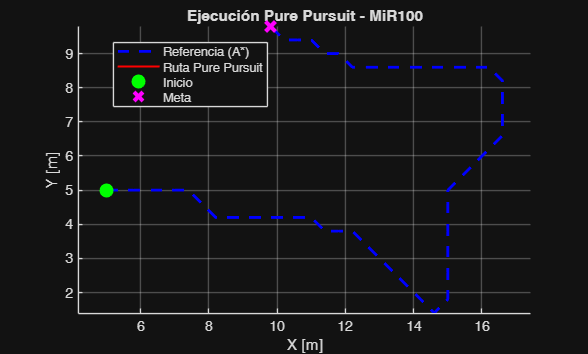


% Frecuencia de muestreo (dt)
dt = 0.1; 

% --- CONFIGURACIÓN DE LA GRÁFICA FINAL ---
figure('Name', 'Control Pure Pursuit MiR100');
hold on; grid on; axis equal;
xlabel('X [m]'); ylabel('Y [m]');
title('Ejecución Pure Pursuit - MiR100');

% 1. Trayectoria de referencia (A*) -> Línea punteada azul ('b--')
h_ref = plot(waypoints_mir100(:,1), waypoints_mir100(:,2), 'b--', 'LineWidth', 2); 

% 2. Punto de INICIO -> Círculo verde ('go')
h_inicio = plot(waypoints_mir100(1,1), waypoints_mir100(1,2), 'go', 'MarkerSize', 8, 'LineWidth', 2, 'MarkerFaceColor', 'g');

% 3. Punto FINAL (Meta) -> 'x' en magenta ('mx')
h_meta = plot(waypoints_mir100(end,1), waypoints_mir100(end,2), 'mx', 'MarkerSize', 10, 'LineWidth', 3);

% 4. Trayectoria realizada por Pure Pursuit -> Línea continua roja ('r-')
h_trayectoria_robot = plot(pose_actual(1), pose_actual(2), 'r-', 'LineWidth', 1.5);

% Agregar leyenda para identificar cada elemento
legend([h_ref, h_trayectoria_robot, h_inicio, h_meta], ...
       {'Referencia (A*)', 'Ruta Pure Pursuit', 'Inicio', 'Meta'}, ...
       'Location', 'best');

% --- INICIALIZACIÓN DE VARIABLES PARA EL HISTORIAL ---
tiempo_actual = 0;
historial_t = [];
historial_v = [];
historial_w = [];
historial_e_lat = [];


% Bucle de control cinemático diferencial
while distancia_a_meta > tolerancia_meta
    
    % Obtener comandos de velocidad del controlador
    [v, w] = controladorPP(pose_actual);
    
    % --- CÁLCULO DEL ERROR LATERAL ---
    % Calculamos la distancia desde la pose actual a todos los waypoints
    distancias_path = sqrt((waypoints_mir100(:,1) - pose_actual(1)).^2 + ...
                           (waypoints_mir100(:,2) - pose_actual(2)).^2);
    % Tomamos la distancia mínima como nuestro error lateral aproximado
    error_lateral = min(distancias_path);
    
    % Guardar datos en el historial para las gráficas
    historial_t(end+1) = tiempo_actual;
    historial_v(end+1) = v;
    historial_w(end+1) = w;
    historial_e_lat(end+1) = error_lateral;
    
    % Actualizar la pose del robot usando un modelo cinemático de uniciclo
    pose_actual(1) = pose_actual(1) + v * cos(pose_actual(3)) * dt; % X
    pose_actual(2) = pose_actual(2) + v * sin(pose_actual(3)) * dt; % Y
    pose_actual(3) = pose_actual(3) + w * dt;                       % Theta
    
    % Actualizar gráficos (se añade el nuevo punto a la línea roja)
    set(h_trayectoria_robot, 'XData', [get(h_trayectoria_robot, 'XData'), pose_actual(1)], ...
                             'YData', [get(h_trayectoria_robot, 'YData'), pose_actual(2)]);
    drawnow;
    
    % Recalcular condición de parada
    distancia_a_meta = norm(pose_actual(1:2) - waypoints_mir100(end,:));
    
    % Actualizar el tiempo
    tiempo_actual = tiempo_actual + dt;
end

disp('¡El MiR100 ha llegado a la meta con Pure Pursuit!');

¡El MiR100 ha llegado a la meta con Pure Pursuit!


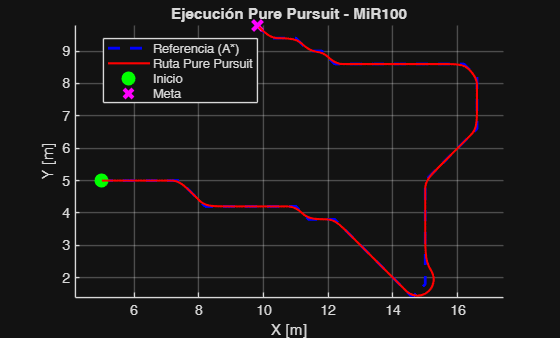

hold off;

%% --- NUEVAS GRÁFICAS: DESEMPEÑO DEL CONTROLADOR PURE PURSUIT ---

disp('Generando gráficas de desempeño del controlador...');

Generando gráficas de desempeño del controlador...


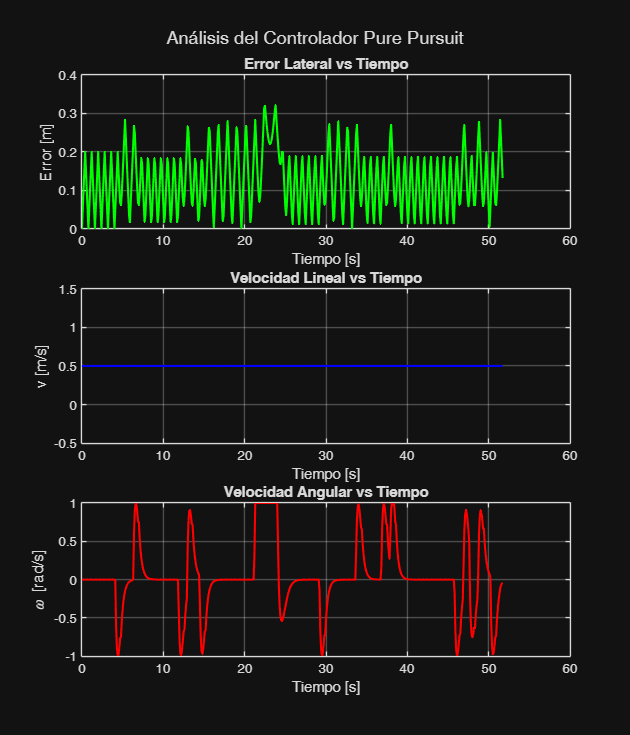


figure('Name', 'Desempeño Pure Pursuit', 'Position', [600, 150, 600, 700]);

% 1. Gráfica de Error Lateral vs Tiempo
subplot(3, 1, 1);
plot(historial_t, historial_e_lat, 'g', 'LineWidth', 1.5);
title('Error Lateral vs Tiempo', 'FontWeight', 'bold');
xlabel('Tiempo [s]');
ylabel('Error [m]');
grid on;

% 2. Gráfica de Velocidad Lineal vs Tiempo
subplot(3, 1, 2);
plot(historial_t, historial_v, 'b', 'LineWidth', 1.5);
title('Velocidad Lineal vs Tiempo', 'FontWeight', 'bold');
xlabel('Tiempo [s]');
ylabel('v [m/s]');
grid on;

% 3. Gráfica de Velocidad Angular vs Tiempo
subplot(3, 1, 3);
plot(historial_t, historial_w, 'r', 'LineWidth', 1.5);
title('Velocidad Angular vs Tiempo', 'FontWeight', 'bold');
xlabel('Tiempo [s]');
ylabel('\omega [rad/s]');
grid on;

% Ajustar el espaciado para que no se sobrepongan los títulos
sgtitle('Análisis del Controlador Pure Pursuit');

# Gráfica final trayecctoria sobre el mapa

%% --- SECCIÓN FINAL: GRÁFICA SOBRE EL MAPA (CARTESIANO) ---

disp('Generando gráfica final sobre el mapa...');

Generando gráfica final sobre el mapa...


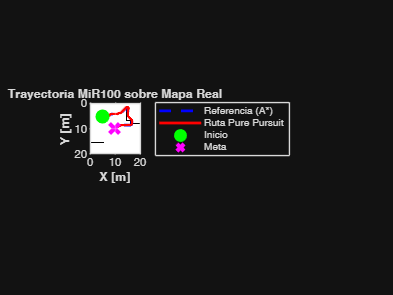


% Extraemos los puntos X e Y que el robot recorrió desde la gráfica anterior
x_pure_pursuit = get(h_trayectoria_robot, 'XData');
y_pure_pursuit = get(h_trayectoria_robot, 'YData');

% Límites del mapa en metros (20x20 según la configuración inicial)
limite_x = 20; 
limite_y = 20; 

% Crear nueva figura
figure('Name', 'Trayectorias sobre Mapa Real', 'Position', [150, 150, 800, 800]);

% 1. PRIMERO mostramos la imagen (esto formatea los ejes por defecto)
imshow('mapa_optimizado.png', 'XData', [0, limite_x], 'YData', [0, limite_y]);

% 2. ¡AHORA SÍ! Activamos hold on para que no se borre nada de lo que pongamos encima
hold on; 

% Activar los ejes y voltear el sistema de coordenadas
axis on; 
%axis xy; %Descomentar para voltear el mapa verticalmente 

% 3. Graficamos las trayectorias y puntos
h_ref_mapa = plot(waypoints_mir100(:,1), waypoints_mir100(:,2), 'b--', 'LineWidth', 2); 
h_pp_mapa = plot(x_pure_pursuit, y_pure_pursuit, 'r-', 'LineWidth', 2);
h_ini_mapa = plot(waypoints_mir100(1,1), waypoints_mir100(1,2), 'go', 'MarkerSize', 8, 'LineWidth', 2, 'MarkerFaceColor', 'g');
h_fin_mapa = plot(waypoints_mir100(end,1), waypoints_mir100(end,2), 'mx', 'MarkerSize', 10, 'LineWidth', 3);

% Configuración visual de los ejes y leyenda
xlabel('X [m]', 'FontWeight', 'bold');
ylabel('Y [m]', 'FontWeight', 'bold');
title('Trayectoria MiR100 sobre Mapa Real');
grid on;

% Forzar los límites
xlim([0 limite_x]);
ylim([0 limite_y]);

% Leyenda (ahora sí encontrará todos los objetos porque no se borraron)
legend([h_ref_mapa, h_pp_mapa, h_ini_mapa, h_fin_mapa], ...
       {'Referencia (A*)', 'Ruta Pure Pursuit', 'Inicio', 'Meta'}, ...
       'Location', 'bestoutside');

hold off;

Métricas de desempeño

%% --- MÉTRICAS DE DESEMPEÑO DEL ERROR LATERAL ---
disp(' ');

disp('--- ANÁLISIS DE ERROR LATERAL (PURE PURSUIT) ---');

--- ANÁLISIS DE ERROR LATERAL (PURE PURSUIT) ---



% 1. Calcular el Error Lateral Máximo
max_e_lat = max(historial_e_lat);

% 2. Calcular el Error Lateral RMS (Root Mean Square)
rms_e_lat = sqrt(mean(historial_e_lat.^2));

% 3. Imprimir los resultados en la Command Window
fprintf('Error Lateral Máximo: %.4f m\n', max_e_lat);

Error Lateral Máximo: 0.3211 m


fprintf('Error Lateral RMS:    %.4f m\n', rms_e_lat);

Error Lateral RMS:    0.1458 m


fprintf('------------------------------------------------\n');

------------------------------------------------


El siguiente es la primera versión de pure pursuit que solo grafica la trayectoria


% % --- INTEGRACIÓN CON PURE PURSUIT PARA MiR100 ---
% 
% % 1. Extraer waypoints físicos de la ruta calculada por el A*
% factor_escala = 10; % 1 metro = 10 pixeles (como definiste al inicio)
% tamano_celda = 3;   % cell_size = 3
% 
% % Suponiendo que le pasas la 'ruta_inicial' o la 'ruta_actual'
% waypoints_mir100 = generarWaypoints(ruta_inicial, tamano_celda, factor_escala);
% 
% % 2. Configurar el controlador Pure Pursuit
% controladorPP = controllerPurePursuit;
% controladorPP.Waypoints = waypoints_mir100;
% 
% % Parámetros específicos para un MiR100 (ajustables)
% controladorPP.DesiredLinearVelocity = 0.5; % Velocidad lineal en m/s
% controladorPP.MaxAngularVelocity = 1.0;    % Velocidad angular máxima rad/s
% controladorPP.LookaheadDistance = 0.4;     % Distancia de visión (metros)
% 
% % 3. Simulación del ciclo de control del robot
% % Posición inicial del robot [X, Y, Theta(rad)]
% pose_actual = [waypoints_mir100(1,1), waypoints_mir100(1,2), 0]; 
% distancia_a_meta = norm(pose_actual(1:2) - waypoints_mir100(end,:));
% tolerancia_meta = 0.1; % 10 cm de margen de error para llegar
% 
% disp('Iniciando movimiento con Pure Pursuit...');
% 
% % Frecuencia de muestreo (dt)
% dt = 0.1; 
% 
% figure('Name', 'Control Pure Pursuit MiR100');
% hold on; grid on; axis equal;
% plot(waypoints_mir100(:,1), waypoints_mir100(:,2), 'k--', 'LineWidth', 2); % Ruta deseada
% h_trayectoria_robot = plot(pose_actual(1), pose_actual(2), 'b.-', 'LineWidth', 1.5);
% title('Ejecución Pure Pursuit - MiR100');
% xlabel('X (metros)'); ylabel('Y (metros)');
% 
% % Bucle de control cinemático diferencial
% while distancia_a_meta > tolerancia_meta
% 
%     % Obtener comandos de velocidad del controlador
%     [v, w] = controladorPP(pose_actual);
% 
%     % Actualizar la pose del robot usando un modelo cinemático de uniciclo
%     % (En el robot real, aquí enviarías 'v' y 'w' a los motores vía ROS u otra API)
%     pose_actual(1) = pose_actual(1) + v * cos(pose_actual(3)) * dt; % X
%     pose_actual(2) = pose_actual(2) + v * sin(pose_actual(3)) * dt; % Y
%     pose_actual(3) = pose_actual(3) + w * dt;                       % Theta
% 
%     % Actualizar gráficos
%     set(h_trayectoria_robot, 'XData', [get(h_trayectoria_robot, 'XData'), pose_actual(1)], ...
%                              'YData', [get(h_trayectoria_robot, 'YData'), pose_actual(2)]);
%     drawnow;
% 
%     % Recalcular condición de parada
%     distancia_a_meta = norm(pose_actual(1:2) - waypoints_mir100(end,:));
% end
% 
% disp('¡El MiR100 ha llegado a la meta con Pure Pursuit!');
